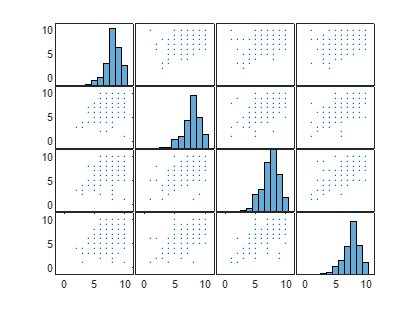

%导入Excel数据
[data, txt] = xlsread('data_1.xls');

%将txt中的ID列找出，然后在data中找到ID为841的行并剔除
idColumn = strcmp(txt(1, :), 'ID');
id841Index = (data(:, idColumn) == 841);
data(id841Index, :) = [];
%定义要画散点图的变量
vars = {'EXPE', 'QUAL', 'LOYA', 'SATI'};
%画出散点图矩阵
plotmatrix(data(:, 2:end));

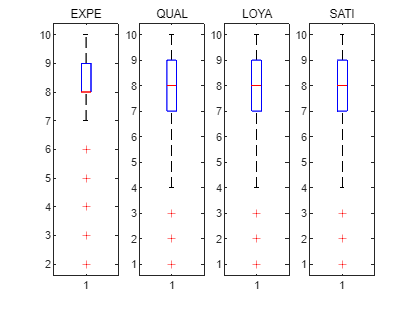

%画出各变量的箱线图
figure;
for i = 1:numel(vars)
    subplot(1, numel(vars), i);
    boxplot(data(:, i+1));
    title(vars{i});
end


%计算pearson相关系数矩阵
[corrMatrix,pValue] = corrcoef(data(:, 2:end));
disp('Correlation Coefficients:');

Correlation Coefficients:


disp(corrMatrix);

    1.0000    0.5913    0.5362    0.5470
    0.5913    1.0000    0.6515    0.7104
    0.5362    0.6515    1.0000    0.7552
    0.5470    0.7104    0.7552    1.0000



disp('p-values:');

p-values:


disp(pValue);

    1.0000    0.0000    0.0000    0.0000
    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000
    0.0000    0.0000    0.0000    1.0000



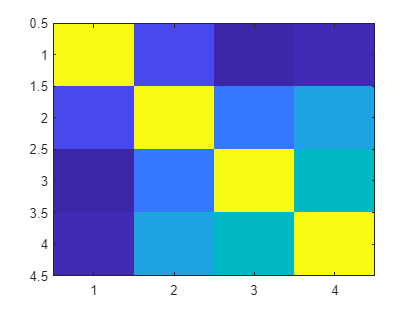

figure;
imagesc(corrMatrix);